We want to explore if there is a way (and how accurate it would be) to detect changes in a given video stream (i.e changes from frame to frame) while only working with a proportion of the pixels.

We are going to try one main method where we are going to use edge detection to figure out where the main areas of the image is. We will then figure out what mean value all the pixels in the areas have. These values will then be compared from frame to frame too see if they differ dramatically (this threshold will be a parameter whose value needs to be set carefully). If there is a different amount of areas from frame to frame this also signals a change. This method will then be compared to a baseline where we just consider a random subset of pixels and the values of these and how these differ. 

% What proportion of the pixels? Apparently way less?
% Why not just send a low-res image?
% Segmentation?

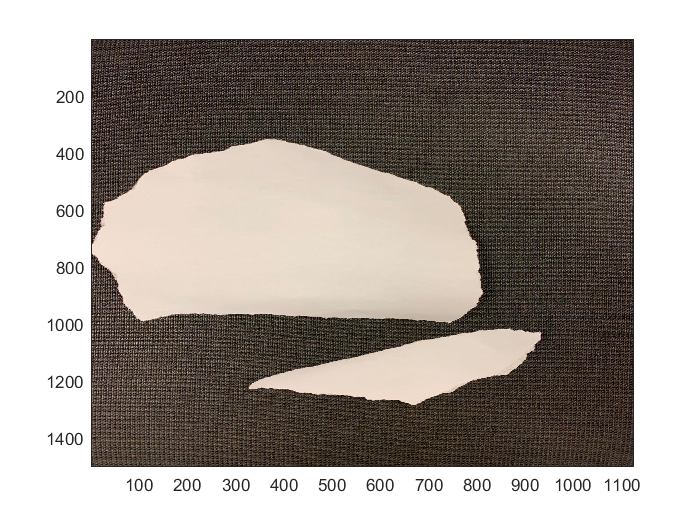

%*- Read 'Image 1', convert to binary image and show.
% I1 = imread('blackboard_images/first.jpg');
I1 = imread('easy2.jpg');
image(I1);

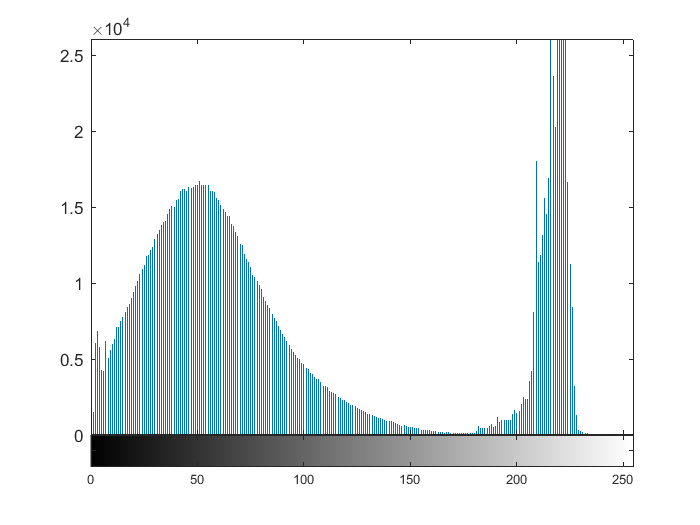

% I1_bw = imbinarize(I1);
imhist(rgb2gray(I1));

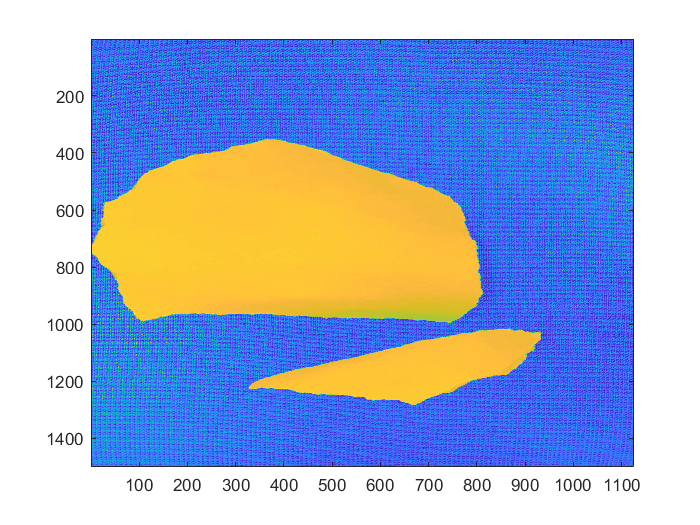

I1_bw2 = rgb2gray(I1);
z = I1_bw2(:,:)>180;
I1_bw = rgb2gray(I1);
image(I1_bw);

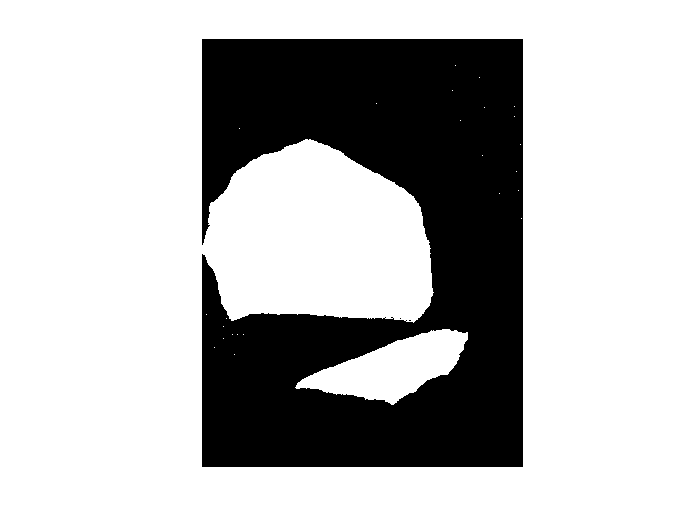

imshow(z);

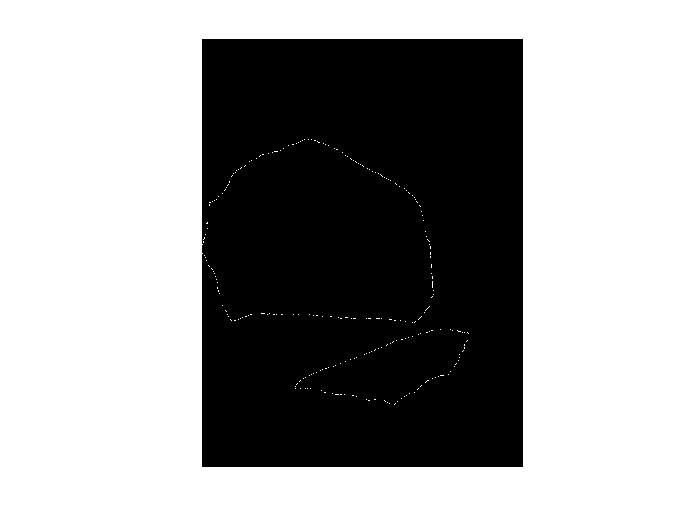

BW1 = edge(I1_bw,'Canny', 0.8);
BW2 = edge(I1_bw,'log');
imshow(BW1);


% Go on to find connected components of the image and then
% extract the pixel values from there and find the mean and such.

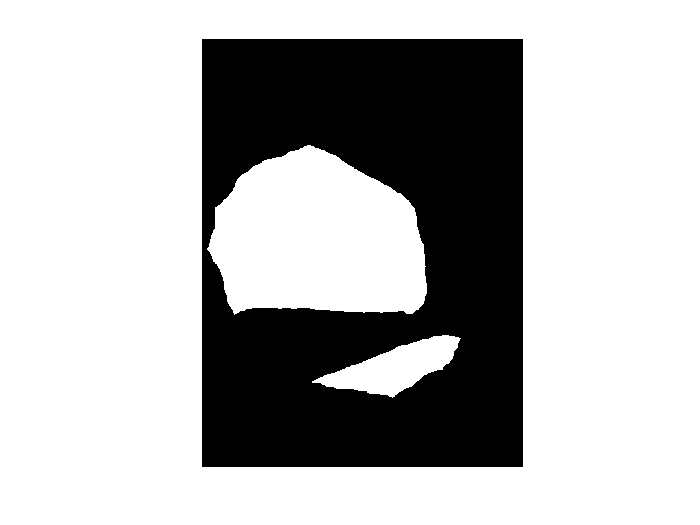

SE = strel('disk', 20);
erodedBW = imerode(z, SE);
imshow(erodedBW);   

erodedBW = logical(erodedBW)

erodedBW = 1500×1125 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

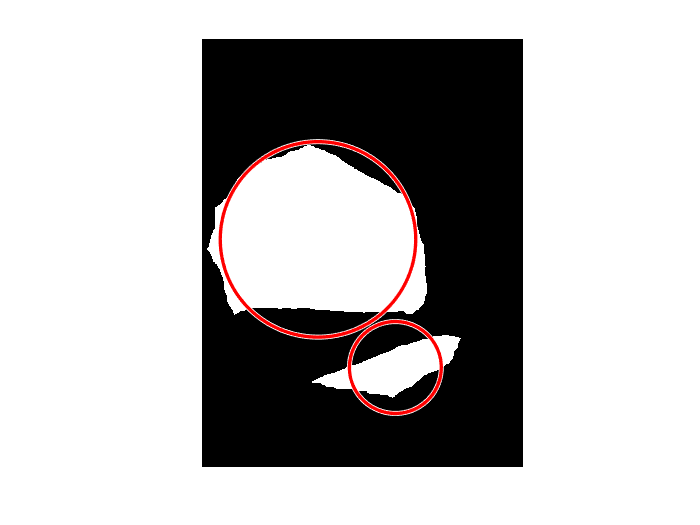

stats = regionprops('table',erodedBW,'Centroid',...
    'MajorAxisLength','MinorAxisLength');

centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;

hold on
viscircles(centers,radii);
hold off

CC = bwconncomp(erodedBW)

CC = struct with fields:
    Connectivity: 8
       ImageSize: [1500 1125]
      NumObjects: 2
    PixelIdxList: {[349958×1 double]  [53385×1 double]}


pixel_list = CC.PixelIdxList;

I1_bw_flatten = reshape(I1_bw.',1,[])

I1_bw_flatten = 1×1687500 uint8 row vector
   84   58   21    4    6    7   20   47   93   53   29   42   54   34   12   11   46   81   68   41   48   44   25   29   17    3   43   85   59   25   21   16   14    9   19   22   67   99   51   21   34   61   45   28   56   66   43   34   26   13


means = [];
for index_list = pixel_list
    for index = index_list
        C = cell2mat(index);
        sum_of_values = uint64(0);
        for j = 1:length(C)
            sum_of_values = sum_of_values + uint64(I1_bw_flatten(C(j)));
        end
        sum_of_values = sum_of_values/length(C);
        means(end+1) = sum_of_values;
    end
end
means

means =    119   138


%I2 = imread('blackboard_images/second.jpg');
%image(I2);

%I3 = imread('blackboard_images/third.jpg');
%image(I3);

%I4 = imread('blackboard_images/fourth.jpg');
%image(I4);

%I5 = imread('blackboard_images/fifth.jpg');
%image(I5);